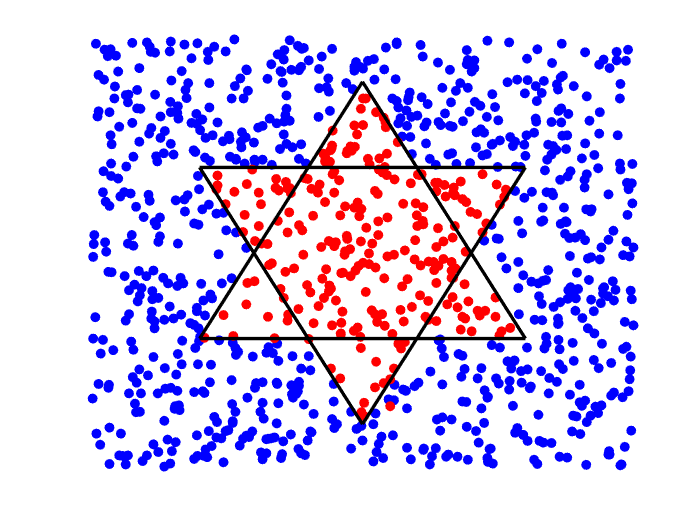

%data genereren
[data_XA, data_YA, data_XB, data_YB] = random_data_generator(1000,500, "Ster");
%    matrix met datapunten
%     klasse A | klasse B
% 1      x_a   |   x_b   
% 2      y_a   |   y_b
% 3       1    |    0
% 4       0    |    1
data = [data_XA data_XB; data_YA data_YB; ones(1,length(data_XA)) zeros(1,length(data_XB)); zeros(1,length(data_XA)) ones(1,length(data_XB))];
data = perturbate_star_data(data,0.02,0.05,100);

x_tot = linspace (0.2,0.8);
x1 = linspace (0.2,0.5);
x2 = linspace (0.5,0.8);
y1 = (0*x_tot) + 0.7;
y2 = -2*x1 + 1.1;
y3 = 2*x2 - 0.9;
y4 = (0*x_tot) + 0.3;
y5 = 2*x1 - 0.1;
y6 = -2*x2 + 1.9;

data_XA = {};
data_YA = {};
data_XB = {};
data_YB = {};

for i = 1:length(data)
    if (data(3,i) == 0) && (data(4,i) == 1) 
        data_XB = [data_XB, data(1,i)];
        data_YB = [data_YB, data(2,i)];
    else
        data_XA = [data_XA, data(1,i)];
        data_YA = [data_YA, data(2,i)];
    end
end

data_XA = cell2mat(data_XA);
data_YA = cell2mat(data_YA);
data_XB = cell2mat(data_XB);
data_YB = cell2mat(data_YB);

figure
hold on
axis([0 1 0 1])
scatter(data_XB,data_YB,'blue','filled')
scatter(data_XA,data_YA,'red','filled')
plot(x_tot,y1,'black','LineWidth',2);
plot(x1,y2,'black','LineWidth',2);
plot(x2,y3,'black','LineWidth',2);
plot(x_tot,y4,'black','LineWidth',2);
plot(x1,y5,'black','LineWidth',2);
plot(x2,y6,'black','LineWidth',2);
color = 'none';
set(gca,'XColor',color,'YColor',color,'TickDir','out')
hold off